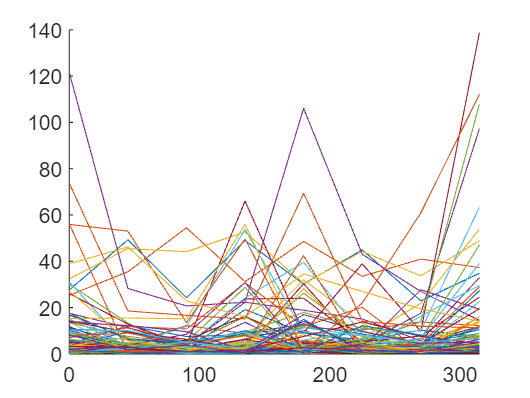

clear,clc
tic
close all
load direction_data.mat
data = direction_data{70}.document_properties.stimulus_tuningcurve.response_mean;
ang = direction_data{70}.document_properties.stimulus_tuningcurve.independent_variable_value;
hold on
for i = 1:length(direction_data)
    plot( direction_data{i}.document_properties.stimulus_tuningcurve.independent_variable_value, ...
        direction_data{i}.document_properties.stimulus_tuningcurve.response_mean)
end
hold off

toc

历时 0.878284 秒。


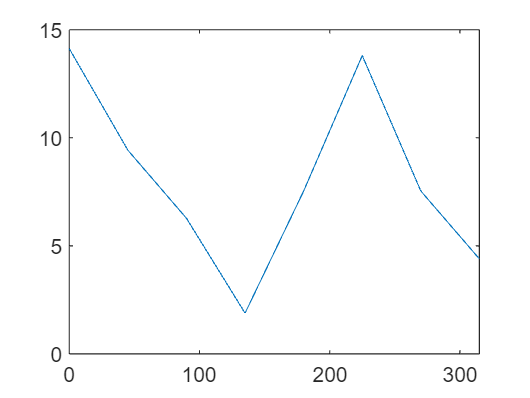

plot(ang,data) 

tic;
[RP,OP,RN,SIG,lik] = bayes_grid_function(data,ang);
toc;

历时 5645.992470 秒。


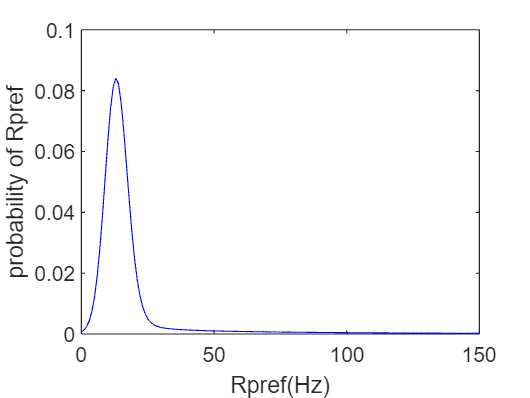

[M,I] = max(lik{6},[],'all'); % get maximum liklihood of parameters value and get the index of parammatlab:helpview('matlab','error_nomem')eters
[i,j,k,h] = ind2sub(size(lik),I);

p_rp =sum(sum(sum(lik{6},4,'omitmissing'),3),2);
p_rp = p_rp/sum(p_rp); 
p_ang = squeeze(sum(sum(sum(lik{6},4,'omitmissing'),3),1));
p_ang = p_ang/sum(p_ang);
p_rn = squeeze(sum(sum(sum(lik{6},4,'omitmissing'),2),1)); 
p_rn = p_rn/sum(p_rn);
p_sig = squeeze(sum(sum(sum(lik{6},3,'omitmissing'),2),1));
p_sig = p_sig/sum(p_sig);
p_noise = zeros(length(lik),1);
for i = 1:length(lik)
p_noise(i) = sum(lik{i},'all','omitmissing');
end
p_noise = p_noise./sum(p_noise);

plot((0:150),p_rp,'b'),% Rp
xlabel("Rpref(Hz)"), 
ylabel("probability of Rpref"),

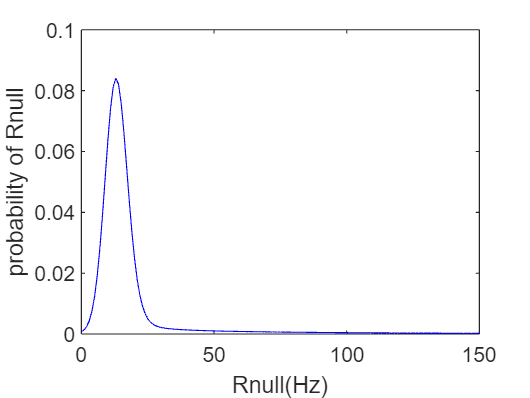


plot((0:150),p_rn,'b'),% Rn
xlabel("Rnull(Hz)"),
ylabel("probability of Rnull"),

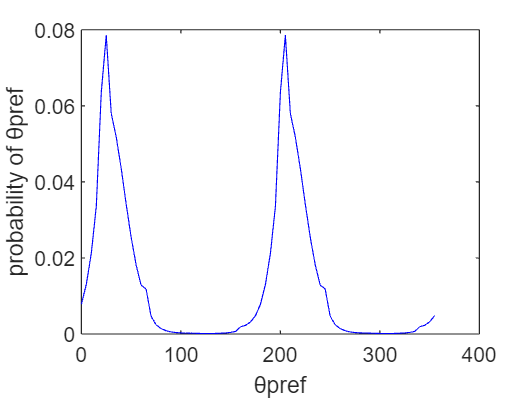


plot(0:5:359,p_ang,'b'),
xlabel("θpref"),
ylabel("probability of θpref"),

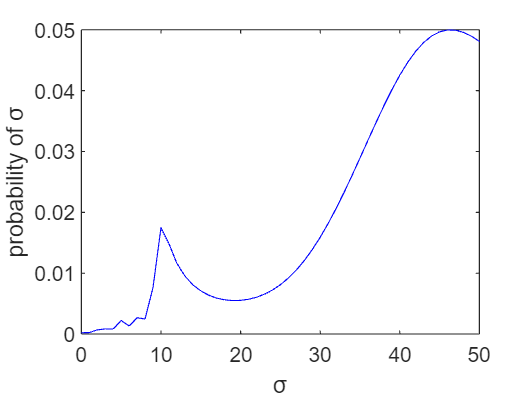


plot(0:50,p_sig,'b'),
xlabel("σ"),
ylabel("probability of σ"),

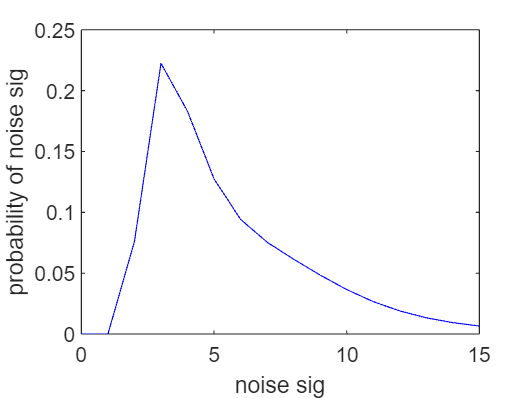


plot(0:15,p_noise,'b'),
xlabel("noise sig"),
ylabel("probability of noise sig"),